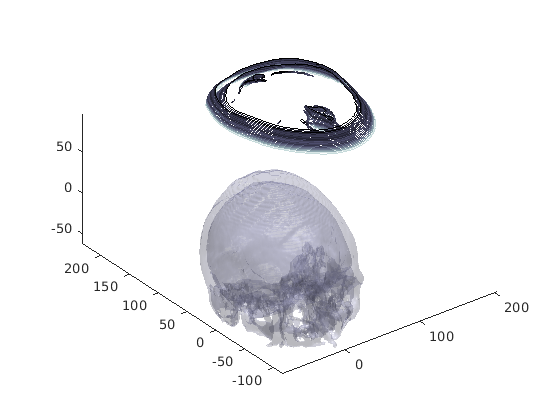

%Variables

global xmin;
global xmax;
global ymin;
global ymax;

xmin = 100;
xmax = 150;
ymin = 70;
ymax = 120;

[VV,ss,dd] = dicomreadVolume(fullfile('./Skull_Tumor/Skull_Tumor/')); 
VV = squeeze(VV);
NSlides = 112;

%Begins from 112 not from 1
tumor_begin_slice = NSlides-42;
tumor_end_slice = NSlides-24;

%Empirically we know the tumor is, on default coordinates,
%inside xmax= xmin=,ymax= ymin=
%The default y is what for us is width and X is depth
 
% for k=tumor_begin_slice:tumor_end_slice
%     for i=1:size(VV,1)
%         for j=1:size(VV,2)
%             if(not(isTumor(i,j)))
%                 VV(i,j,k) = 0;
%             end
%         end
%     end
% end

printSkull;
hold on

%Color
colormap 'Bone';
tumor_slices = tumor_begin_slice:tumor_end_slice;

%Ds = smooth3(VV);
%hiso = patch(isosurface(Ds,5),'FaceColor',[1,.75,.65],'EdgeColor','none');
%isonormals(Ds,hiso)

contourslice(Ds,[],[],tumor_slices,1);
view(3);

%axis tight 




function res=isTumor(i,j)

global xmin;
global xmax;
global ymin;
global ymax;

    res = (i > xmin && i < xmax &&...
        j > ymin && j < ymax);
end
